## TOPIC 17: Text and structure arrays

ENGR105, 10/29/20

#### Practice Problem: the central dogma of molecular biology

The **central dogma of molecular biology** is an explanation of the genetic flow of information in a biological system, often stated as "DNA makes RNA, and RNA makes protein." *Depicted visually (from *[wikipedia](https://en.wikipedia.org/wiki/Protein_production)*):*

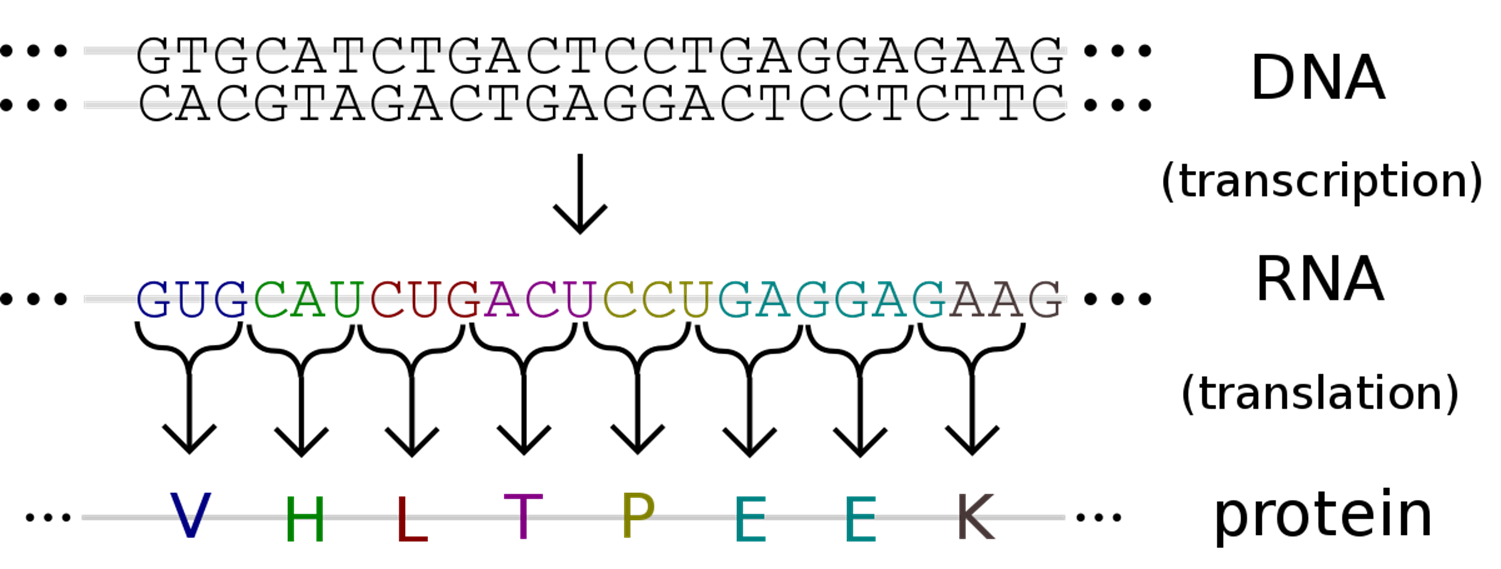

*Key terms for this problem:*

- **DNA**: the "genetic blueprint" for life. Strands of DNA are biopolymers consisting of a sequence of monomers, known as nucleotides. Each nucleotide consists of one base (cytosine [**C**], guanine [**G**], adenine [**A**] or thymine [**T**]), a sugar (deoxyribose), and a phosphate group. **Information is stored in the sequence of bases**, and DNA sequences are represented as a sequence of A, T, C, and G. Example: `TCTTGTTTTATTG`

- **mRNA**: the "instructions copied from DNA" dictating how to construct a protein. Like DNA, strands of RNA are biopolymers consisting of a sequence of nucleotide monomers. In this case, each nucleotide consists of one base (cytosine [**C**], guanine [**G**], adenine [**A**] or uracil [**U**]), a sugar (ribose), and a phosphate group. An mRNA strand is** produced from its DNA template**, with all bases matching except with uracils replacing thymines. Information is stored in the sequence of bases, and mRNA sequences are represented as a sequence of A, U, C, and G. Example corresponding to the above: `UCUUGUUUUAUUG`

- **Protein**: the "functional units" produced from an mRNA template. Encoded from mRNA, proteins are biopolymers that consist of a sequence of amino acid monomers. There are 20 naturally occuring amino acids.

- **Codon**: sequence of three bases that specify which amino acid will be added next to *a protein that is being constructed*.

% List of codons. Note the use of importdata()
codon_list = importdata('codonList.txt');
disp(codon_list)

    {'TTT,Phenylalanine,F'}
    {'TTC,Phenylalanine,F'}
    {'TTA,Leucine,L'      }
    {'TTG,Leucine,L'      }
    {'TCT,Serine,S'       }
    {'TCC,Serine,S'       }
    {'TCA,Serine,S'       }
    {'TCG,Serine,S'       }
    {'TAT,Tyrosine,Y'     }
    {'TAC,Tyrosine,Y'     }
    {'TAA,Stop,X'         }
    {'TAG,Stop,X'         }
    {'TGT,Cysteine,C'     }
    {'TGC,Cysteine,C'     }
    {'TGA,Stop,X'         }
    {'TGG,Tryptophan,W'   }
    {'CTT,Leucine,L'      }
    {'CTC,Leucine,L'      }
    {'CTA,Leucine,L'      }
    {'CTG,Leucine,L'      }
    {'CCT,Proline,P'      }
    {'CCC,Proline,P'      }
    {'CCA,Proline,P'      }
    {'CCG,Proline,P'      }
    {'CAT,Histidine,H'    }
    {'CAC,Histidine,H'    }
    {'CAA,Glutamine,Q'    }
    {'CAG,Glutamine,Q'    }
    {'CGT,Arginine,R'     }
    {'CGC,Arginine,R'     }
    {'CGA,Arginine,R'     }
    {'CGG,Arginine,R'     }
    {'ATT,Isoleucine,I'   }
    {'ATC,Isoleucine,I'   }
    {'ATA,Isoleucine,I'   }
    {'ATG,Methionine

**Important notes: **

- Genes occur in sets of three bases. One codon (three bases) specifies an amino acid.

- Methionine (DNA base sequence `ATG`) is nearly always the "Start" codon, indicating the start of a sequence for a gene.

- There are three common "Stop" codons that indicate where a gene sequence stops: DNA base sequences `TAA`, `TAG`, `TGA`.

- We are representing these biomolecules as text. Remember that these correspond to* different chemical structures*.

*Short summary:*

- DNA specifies mRNA, which encodes the protein to be made.

- DNA/mRNA can be represented as text - either ATCG or AUCG

- Protein can be represented as text - a string of one of twenty letters.

In this problem, we will analyze this flow of biological information describing the **"spike"** protein on the membrane of **severe acute respiratory syndrome coronavirus 2 (SARS-CoV-2)**.SARS-CoV-2 is an enveloped, *positive-sense*, single-stranded RNA virus that causes coronavirus disease 2019 (COVID-19). Virus particles include the RNA genetic material and structural proteins needed for invasion of host cells. Once inside the cell the infecting RNA is used to encode structural proteins that make up virus particles, nonstructural proteins that direct virus assembly, transcription, replication and host control and accessory proteins whose function has not been determined. 

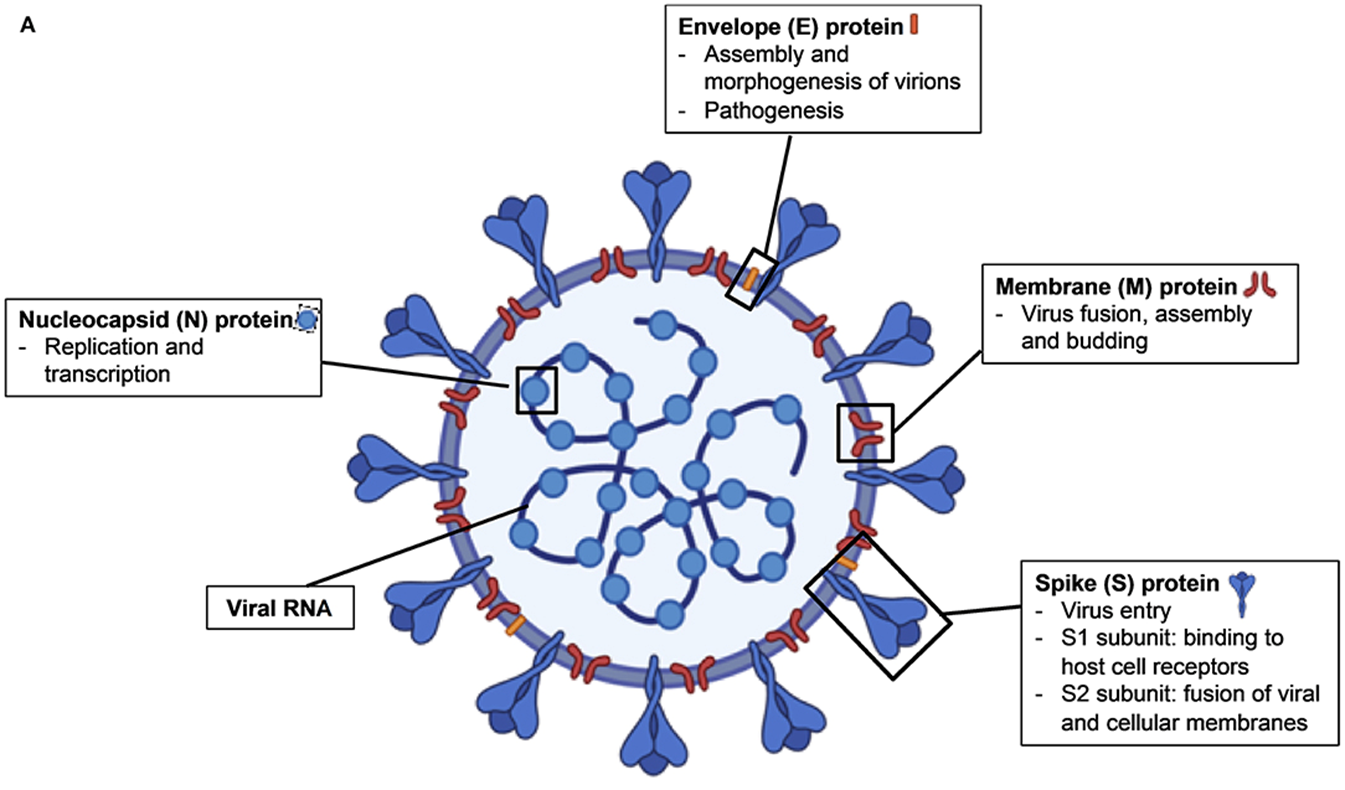

***Source DOI: ***[***10.3389/fimmu.2020.00879***](https://www.frontiersin.org/articles/10.3389/fimmu.2020.00879/full)

The structural proteins of SARS-CoV-2 include the envelope protein, **spike or surface glycoprotein**, membrane protein and the nucleocapsid protein. **The spike glycoprotein is found on the outside of the virus particle and gives coronavirus viruses their crown-like appearance. This glycoprotein mediates attachment of the virus particle and entry into the host cell.** This protein is an *important target* for vaccine development, antibody therapies and diagnostic antigen-based tests.

***Key resources and references:***

- Review of SARS-CoV-2 and COVID-19: [https://www.nature.com/articles/s41579-020-00459-7](https://www.nature.com/articles/s41579-020-00459-7)

- Genomic information (Wuhan-Hu-1): [https://www.ncbi.nlm.nih.gov/nuccore/NC_045512](https://www.ncbi.nlm.nih.gov/nuccore/NC_045512)

- General information about coronaviruses: [https://www.ncbi.nlm.nih.gov/pmc/articles/PMC4369385/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC4369385/)

**Problem statement**

Given a DNA primer (a short sequence of DNA representing the first few bases of a given gene) for the spike glycoprotein and the genome of SARS-CoV-2, answer the following questions:

**Question 1:** how many bases are in the SARS-CoV-2 genome?

**Question 2:** how many of *each* base appear in the genome?

**Question 3:** given a primer, what is the DNA sequence for the spike glycoprotein? How many bases long is it?

**Question 4:** what is the mRNA transcript of the spike protein?

**Question 5:** What is the amino acid sequence of the spike protein?

**Question 6:** How many of each amino acid are in the spike protein?

**First thing to do: organize information that is provided**

*SARS-CoV-2 genome:*

% Import genomic information as one long character array.
% NOTE: difference from importdata()
sarsCov2_genome = fileread('sarsCov2_genome.txt');  % Read text file
sarsCov2_genome = sarsCov2_genome(isletter(sarsCov2_genome));   % remove spaces and commas
sarsCov2_genome = upper(sarsCov2_genome);   % Convert to upper case
disp(sarsCov2_genome)

ATTAAAGGTTTATACCTTCCCAGGTAACAAACCAACCAACTTTCGATCTCTTGTAGATCTGTTCTCTAAACGAACTTTAAAATCTGTGTGGCTGTCACTCGGCTGCATGCTTAGTGCACTCACGCAGTATAATTAATAACTAATTACTGTCGTTGACAGGACACGAGTAACTCGTCTATCTTCTGCAGGCTGCTTACGGTTTCGTCCGTGTTGCAGCCGATCATCAGCACATCTAGGTTTCGTCCGGGTGTGACCGAAAGGTAAGATGGAGAGCCTTGTCCCTGGTTTCAACGAGAAAACACACGTCCAACTCAGTTTGCCTGTTTTACAGGTTCGCGACGTGCTCGTACGTGGCTTTGGAGACTCCGTGGAGGAGGTCTTATCAGAGGCACGTCAACATCTTAAAGATGGCACTTGTGGCTTAGTAGAAGTTGAAAAAGGCGTTTTGCCTCAACTTGAACAGCCCTATGTGTTCATCAAACGTTCGGATGCTCGAACTGCACCTCATGGTCATGTTATGGTTGAGCTGGTAGCAGAACTCGAAGGCATTCAGTACGGTCGTAGTGGTGAGACACTTGGTGTCCTTGTCCCTCATGTGGGCGAAATACCAGTGGCTTACCGCAAGGTTCTTCTTCGTAAGAACGGTAATAAAGGAGCTGGTGGCCATAGTTACGGCGCCGATCTAAAGTCATTTGACTTAGGCGACGAGCTTGGCACTGATCCTTATGAAGATTTTCAAGAAAACTGGAACACTAAACATAGCAGTGGTGTTACCCGTGAACTCATGCGTGAGCTTAACGGAGGGGCATACACTCGCTATGTCGATAACAACTTCTGTGGCCCTGATGGCTACCCTCTTGAGTGCATTAAAGACCTTCTAGCACGTGCTGGTAAAGCTTCATGCACTTTGTCCGAACAACTGGACTTTATTGACACTAAGAGGGGTGTATACTGCTGCCGTGAACATGAGCATGAAATTGCTTGGTACACGGAACGTTCT

*Spike protein primer:*

% DNA sequence that you know starts the gene
spike_FWprimer = 'ATGTTTGTTTTTCTTGTTTTATTG';

*Codon information - reorganize into a three column cell array for easier accessibility:*

% NOTE: one cell in codon_list (imported above) is a line of information
% containing 1) the nucleotides, the name, and abbreviation for
% each amino acid. We want each of these three items in a separate column

% Preallocate cell array
codons = cell(length(codon_list),3);

% Loop through each entry in the list of codons
for k = 1:length(codon_list)
    % Read character arrays from the k-th row
    codon_row = codon_list{k};
    
    % Determine indices where commas occur
    ind = strfind(codon_row,',');
    
    % First column: bases
    codons{k,1} = codon_row(1:ind(1)-1);
    % Second column: corresponding codon name
    codons{k,2} = codon_row(ind(1)+1:ind(2)-1);
    % Third column: Amino acid
    codons{k,3} = codon_row(ind(2)+1:end);
end

**Note**: the codons listed are given in terms of *DNA bases*.

**Question 1:** how many bases are in the SARS-CoV-2 genome?

% Number of bases equals number of elements in the character vector
numBases = length(sarsCov2_genome)

numBases = 29903

**Question 2:** how many of *each* base appear in the genome?

**Note**: for this problem we consider only one strand.

% Step 1: Determine how many of each base are in the genome
base_A = length(strfind(sarsCov2_genome, 'A'))

base_A = 8954

base_T = length(strfind(sarsCov2_genome, 'T'))

base_T = 9594

base_C = length(strfind(sarsCov2_genome, 'C'))

base_C = 5492

base_G = length(strfind(sarsCov2_genome, 'G'))

base_G = 5863

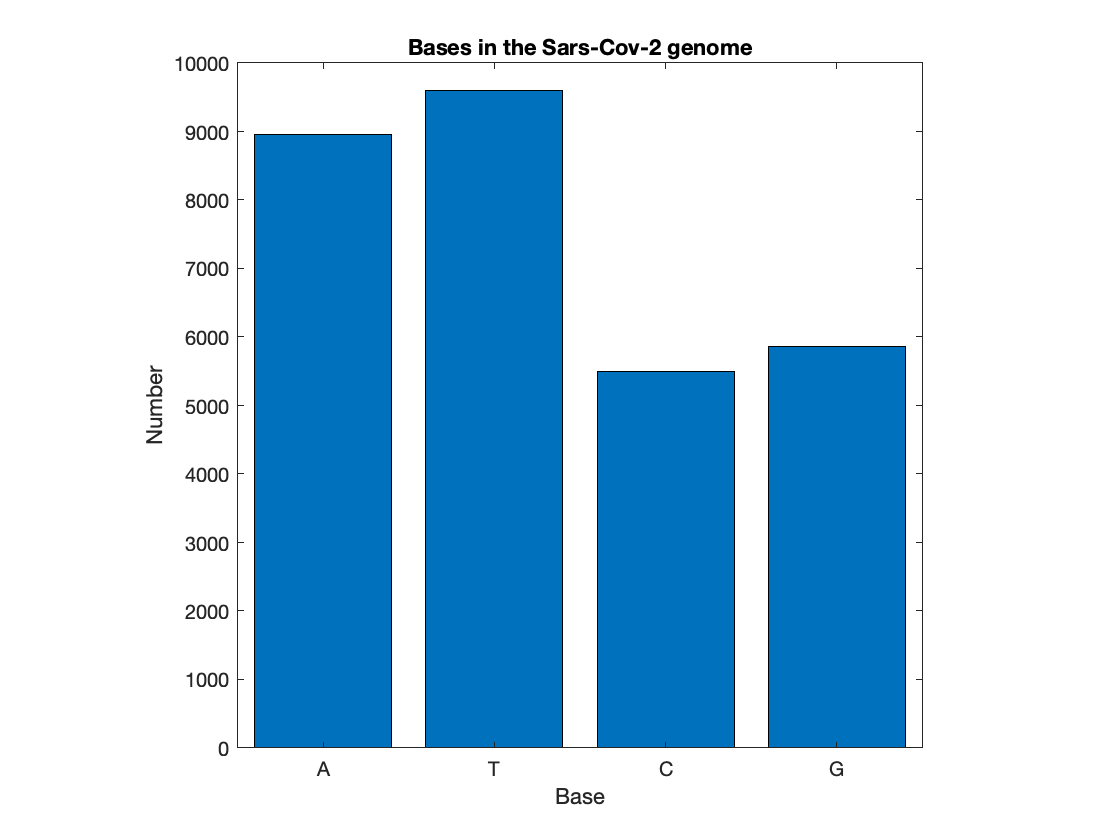


% Step 2: Plotting
% Create cell array containing each x label
xval = {'A','T','C','G'};
% Convert cell array to categorical and then reorder to be in the same
% order
xval2 = categorical(xval);
xval2 = reordercats(xval2,xval)';

% Make bar graph
bar(xval2,[base_A,base_T,base_C,base_G]);
title('Bases in the Sars-Cov-2 genome')
axis square
ylabel('Number');
xlabel('Base');

**Question 3:** given a primer, what is the DNA sequence for the spike glycoprotein? How many bases long is it?

% Step 1: Find the index in the genome where the gene starts 
DNA_start = strfind(sarsCov2_genome, spike_FWprimer)

DNA_start = 21563

% Define the DNA sequence starting at taht position
spike_DNA = sarsCov2_genome(DNA_start:end)

spike_DNA = 'ATGTTTGTTTTTCTTGTTTTATTGCCACTAGTCTCTAGTCAGTGTGTTAATCTTACAACCAGAACTCAATTACCCCCTGCATACACTAATTCTTTCACACGTGGTGTTTATTACCCTGACAAAGTTTTCAGATCCTCAGTTTTACATTCAACTCAGGACTTGTTCTTACCTTTCTTTTCCAATGTTACTTGGTTCCATGCTATACATGTCTCTGGGACCAATGGTACTAAGAGGTTTGATAACCCTGTCCTACCATTTAATGATGGTGTTTATTTTGCTTCCACTGAGAAGTCTAACATAATAAGAGGCTGGATTTTTGGTACTACTTTAGATTCGAAGACCCAGTCCCTACTTATTGTTAATAACGCTACTAATGTTGTTATTAAAGTCTGTGAATTTCAATTTTGTAATGATCCATTTTTGGGTGTTTATTACCACAAAAACAACAAAAGTTGGATGGAAAGTGAGTTCAGAGTTTATTCTAGTGCGAATAATTGCACTTTTGAATATGTCTCTCAGCCTTTTCTTATGGACCTTGAAGGAAAACAGGGTAATTTCAAAAATCTTAGGGAATTTGTGTTTAAGAATATTGATGGTTATTTTAAAATATATTCTAAGCACACGCCTATTAATTTAGTGCGTGATCTCCCTCAGGGTTTTTCGGCTTTAGAACCATTGGTAGATTTGCCAATAGGTATTAACATCACTAGGTTTCAAACTTTACTTGCTTTACATAGAAGTTATTTGACTCCTGGTGATTCTTCTTCAGGTTGGACAGCTGGTGCTGCAGCTTATTATGTGGGTTATCTTCAACCTAGGACTTTTCTATTAAAATATAATGAAAATGGAACCATTACAGATGCTGTAGACTGTGCACTTGACCCTCTCTCAGAAACAAAGTGTACGTTGAAATCCTTCACTGTAGAAAAAGGAATCTATCAAACTTCTAACTTTAGAGTCCAACCAACAGAATCTATTGTTAGATTT

% Step 2: determine length of gene
% Goal: find each instance of a "possible" stop codon. In this case, the
% first one that occurs after a "multiple of three bases" will be it.
possibleStops = [];
stopCodons = ['TAA'; 'TAG'; 'TGA']

stopCodons = 3×3 char array
    'TAA'
    'TAG'
    'TGA'



%Loop through sequence to find potential stop codons 

for k = 1:3
    % stop codon to be considered 
    tempStop = stopCodons(k,:);
    %find and add potential stop locations 
    possibleStops = [possibleStops, strfind(spike_DNA, tempStop)];
end

%find the first stop position that is consisitent 
possibleStops = sort(possibleStops, 'ascend')

possibleStops =     29    36    48    87   117   228   237   240   258   261   285   294   299   302   329   360   363   372   384   393   408   411   465   483   492   504   537   552   567   582   591   603   615   630   635   642   668   680   692   699   708   735   746   756   816   830   837   840   866   879



%find positions in modulus of 3
lastCodon = possibleStops(mod(possibleStops,3) == 1);
lastBase = lastCodon(1) + 2;
% DNA sequence of spike protein 
spike_DNA = spike_DNA(1:lastBase)

spike_DNA = 'ATGTTTGTTTTTCTTGTTTTATTGCCACTAGTCTCTAGTCAGTGTGTTAATCTTACAACCAGAACTCAATTACCCCCTGCATACACTAATTCTTTCACACGTGGTGTTTATTACCCTGACAAAGTTTTCAGATCCTCAGTTTTACATTCAACTCAGGACTTGTTCTTACCTTTCTTTTCCAATGTTACTTGGTTCCATGCTATACATGTCTCTGGGACCAATGGTACTAAGAGGTTTGATAACCCTGTCCTACCATTTAATGATGGTGTTTATTTTGCTTCCACTGAGAAGTCTAACATAATAAGAGGCTGGATTTTTGGTACTACTTTAGATTCGAAGACCCAGTCCCTACTTATTGTTAATAACGCTACTAATGTTGTTATTAAAGTCTGTGAATTTCAATTTTGTAATGATCCATTTTTGGGTGTTTATTACCACAAAAACAACAAAAGTTGGATGGAAAGTGAGTTCAGAGTTTATTCTAGTGCGAATAATTGCACTTTTGAATATGTCTCTCAGCCTTTTCTTATGGACCTTGAAGGAAAACAGGGTAATTTCAAAAATCTTAGGGAATTTGTGTTTAAGAATATTGATGGTTATTTTAAAATATATTCTAAGCACACGCCTATTAATTTAGTGCGTGATCTCCCTCAGGGTTTTTCGGCTTTAGAACCATTGGTAGATTTGCCAATAGGTATTAACATCACTAGGTTTCAAACTTTACTTGCTTTACATAGAAGTTATTTGACTCCTGGTGATTCTTCTTCAGGTTGGACAGCTGGTGCTGCAGCTTATTATGTGGGTTATCTTCAACCTAGGACTTTTCTATTAAAATATAATGAAAATGGAACCATTACAGATGCTGTAGACTGTGCACTTGACCCTCTCTCAGAAACAAAGTGTACGTTGAAATCCTTCACTGTAGAAAAAGGAATCTATCAAACTTCTAACTTTAGAGTCCAACCAACAGAATCTATTGTTAGATTT

disp(spike_DNA)

ATGTTTGTTTTTCTTGTTTTATTGCCACTAGTCTCTAGTCAGTGTGTTAATCTTACAACCAGAACTCAATTACCCCCTGCATACACTAATTCTTTCACACGTGGTGTTTATTACCCTGACAAAGTTTTCAGATCCTCAGTTTTACATTCAACTCAGGACTTGTTCTTACCTTTCTTTTCCAATGTTACTTGGTTCCATGCTATACATGTCTCTGGGACCAATGGTACTAAGAGGTTTGATAACCCTGTCCTACCATTTAATGATGGTGTTTATTTTGCTTCCACTGAGAAGTCTAACATAATAAGAGGCTGGATTTTTGGTACTACTTTAGATTCGAAGACCCAGTCCCTACTTATTGTTAATAACGCTACTAATGTTGTTATTAAAGTCTGTGAATTTCAATTTTGTAATGATCCATTTTTGGGTGTTTATTACCACAAAAACAACAAAAGTTGGATGGAAAGTGAGTTCAGAGTTTATTCTAGTGCGAATAATTGCACTTTTGAATATGTCTCTCAGCCTTTTCTTATGGACCTTGAAGGAAAACAGGGTAATTTCAAAAATCTTAGGGAATTTGTGTTTAAGAATATTGATGGTTATTTTAAAATATATTCTAAGCACACGCCTATTAATTTAGTGCGTGATCTCCCTCAGGGTTTTTCGGCTTTAGAACCATTGGTAGATTTGCCAATAGGTATTAACATCACTAGGTTTCAAACTTTACTTGCTTTACATAGAAGTTATTTGACTCCTGGTGATTCTTCTTCAGGTTGGACAGCTGGTGCTGCAGCTTATTATGTGGGTTATCTTCAACCTAGGACTTTTCTATTAAAATATAATGAAAATGGAACCATTACAGATGCTGTAGACTGTGCACTTGACCCTCTCTCAGAAACAAAGTGTACGTTGAAATCCTTCACTGTAGAAAAAGGAATCTATCAAACTTCTAACTTTAGAGTCCAACCAACAGAATCTATTGTTAGATTTCCTAATATTACAA

**Question 4:** what is the mRNA transcript of the spike protein?

% First, initialize the RNA sequence from the DNA sequence
spike_RNA = spike_DNA;

% The difference between DNA and RNA is that RNA contains uracil bases int
% he place of thymine
spike_RNA(spike_DNA == 'T') = 'U';
length(spike_RNA)

ans = 3822

disp(spike_RNA)

AUGUUUGUUUUUCUUGUUUUAUUGCCACUAGUCUCUAGUCAGUGUGUUAAUCUUACAACCAGAACUCAAUUACCCCCUGCAUACACUAAUUCUUUCACACGUGGUGUUUAUUACCCUGACAAAGUUUUCAGAUCCUCAGUUUUACAUUCAACUCAGGACUUGUUCUUACCUUUCUUUUCCAAUGUUACUUGGUUCCAUGCUAUACAUGUCUCUGGGACCAAUGGUACUAAGAGGUUUGAUAACCCUGUCCUACCAUUUAAUGAUGGUGUUUAUUUUGCUUCCACUGAGAAGUCUAACAUAAUAAGAGGCUGGAUUUUUGGUACUACUUUAGAUUCGAAGACCCAGUCCCUACUUAUUGUUAAUAACGCUACUAAUGUUGUUAUUAAAGUCUGUGAAUUUCAAUUUUGUAAUGAUCCAUUUUUGGGUGUUUAUUACCACAAAAACAACAAAAGUUGGAUGGAAAGUGAGUUCAGAGUUUAUUCUAGUGCGAAUAAUUGCACUUUUGAAUAUGUCUCUCAGCCUUUUCUUAUGGACCUUGAAGGAAAACAGGGUAAUUUCAAAAAUCUUAGGGAAUUUGUGUUUAAGAAUAUUGAUGGUUAUUUUAAAAUAUAUUCUAAGCACACGCCUAUUAAUUUAGUGCGUGAUCUCCCUCAGGGUUUUUCGGCUUUAGAACCAUUGGUAGAUUUGCCAAUAGGUAUUAACAUCACUAGGUUUCAAACUUUACUUGCUUUACAUAGAAGUUAUUUGACUCCUGGUGAUUCUUCUUCAGGUUGGACAGCUGGUGCUGCAGCUUAUUAUGUGGGUUAUCUUCAACCUAGGACUUUUCUAUUAAAAUAUAAUGAAAAUGGAACCAUUACAGAUGCUGUAGACUGUGCACUUGACCCUCUCUCAGAAACAAAGUGUACGUUGAAAUCCUUCACUGUAGAAAAAGGAAUCUAUCAAACUUCUAACUUUAGAGUCCAACCAACAGAAUCUAUUGUUAGAUUUCCUAAUAUUACAA

**Question 5:** What is the amino acid sequence of the spike protein? That is, what is the product of protein *translation*.

% Step 1: Preallocate character array to contain protein sequence. Note:
% stop codon is not included in the aminoa cid sequence
spike_protein = blanks(length(spike_DNA)/3-1);


% Step 2: compare each three bases to list of codons to determine
% appropriate amino acod. 
% String array: each line corresponds to a codon. To be used for
% identifying codon
codon_bases = string(codons(:,1));

% Note: we do not consider the Stop Codon
for k = 1:length(spike_protein)-3
    % Based on based pairs in codon, identify the index of the codon we are
    % interested in
    codon_index = codon_bases == string(spike_DNA((1:3)+(k-1)*3));
    
    % Retrive amino acid corresponding to codon and store in protein
    % sequence
    spike_Protein(k) = codons{codon_index,3};
end
length(spike_Protein)

ans = 1270

disp(spike_Protein)

MFVFLVLLPLVSSQCVNLTTRTQLPPAYTNSFTRGVYYPDKVFRSSVLHSTQDLFLPFFSNVTWFHAIHVSGTNGTKRFDNPVLPFNDGVYFASTEKSNIIRGWIFGTTLDSKTQSLLIVNNATNVVIKVCEFQFCNDPFLGVYYHKNNKSWMESEFRVYSSANNCTFEYVSQPFLMDLEGKQGNFKNLREFVFKNIDGYFKIYSKHTPINLVRDLPQGFSALEPLVDLPIGINITRFQTLLALHRSYLTPGDSSSGWTAGAAAYYVGYLQPRTFLLKYNENGTITDAVDCALDPLSETKCTLKSFTVEKGIYQTSNFRVQPTESIVRFPNITNLCPFGEVFNATRFASVYAWNRKRISNCVADYSVLYNSASFSTFKCYGVSPTKLNDLCFTNVYADSFVIRGDEVRQIAPGQTGKIADYNYKLPDDFTGCVIAWNSNNLDSKVGGNYNYLYRLFRKSNLKPFERDISTEIYQAGSTPCNGVEGFNCYFPLQSYGFQPTNGVGYQPYRVVVLSFELLHAPATVCGPKKSTNLVKNKCVNFNFNGLTGTGVLTESNKKFLPFQQFGRDIADTTDAVRDPQTLEILDITPCSFGGVSVITPGTNTSNQVAVLYQDVNCTEVPVAIHADQLTPTWRVYSTGSNVFQTRAGCLIGAEHVNNSYECDIPIGAGICASYQTQTNSPRRARSVASQSIIAYTMSLGAENSVAYSNNSIAIPTNFTISVTTEILPVSMTKTSVDCTMYICGDSTECSNLLLQYGSFCTQLNRALTGIAVEQDKNTQEVFAQVKQIYKTPPIKDFGGFNFSQILPDPSKPSKRSFIEDLLFNKVTLADAGFIKQYGDCLGDIAARDLICAQKFNGLTVLPPLLTDEMIAQYTSALLAGTITSGWTFGAGAALQIPFAMQMAYRFNGIGVTQNVLYENQKLIANQFNSAIGKIQDSLSSTASALGKLQDVVNQNAQALNTLVKQLSSNFGAISSVLNDILSRLDKVEAEVQIDRLITGR

**Question 6:** How many of each amino acid are in the spike protein?

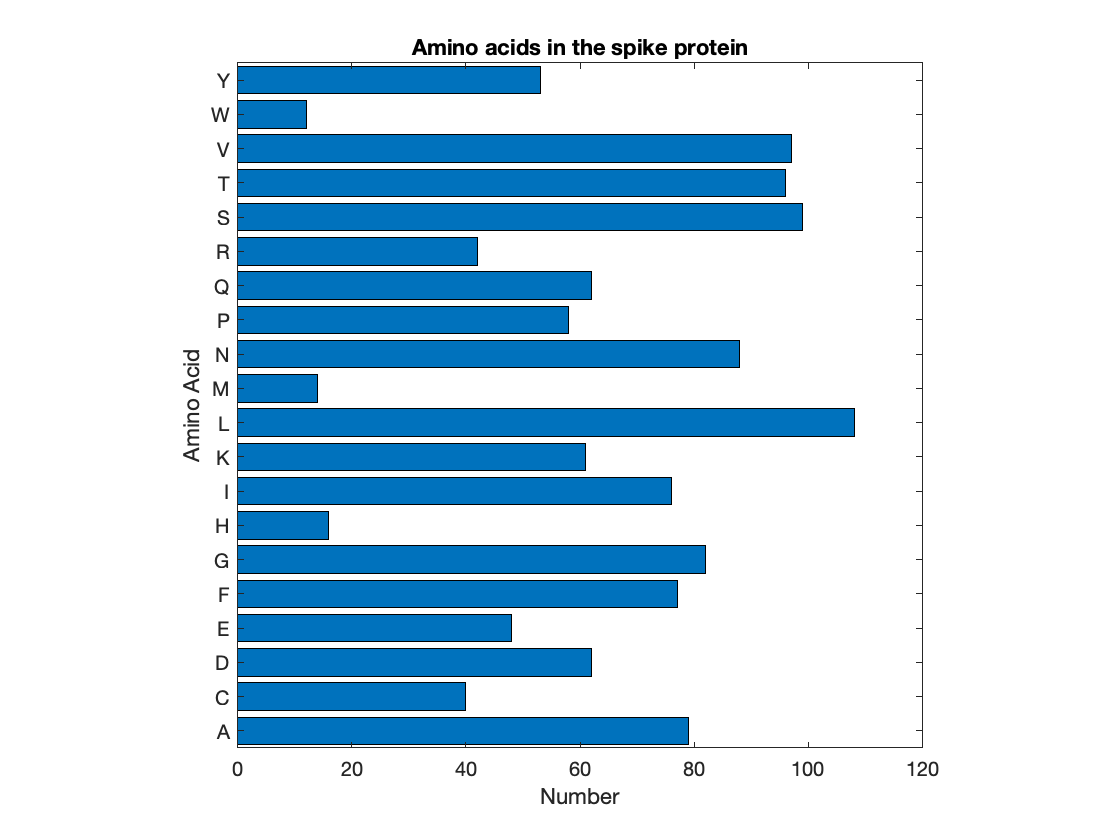

% To solve this: create a cell array containing "unique" amino acids and a
% corresponding vector that specifies if that amino acid has been so far

% Create cell array to store unique amino acids
AA_list = {spike_Protein(1)};

%Create a vector to store the corresponding counts 
AA_count = 1;

% Loop through each amino acid of protien
for k = 2:length(spike_Protein)
    % Create a logical variable
    % True: amino acid has been observed before in protein sequence 
    %False: no match -> new amino acid
    match = false;
    
    % For each identified "unique" amino acid
    for m = 1:length(AA_list)
        % If the amino acids match, increment the number of times it
        % appears
        if strcmp(AA_list{m}, spike_Protein(k))
            AA_count(m) = AA_count(m)+1;
            match = true;
        end
    end
    
    % If the current word did not match, then we have found a new amino
    % acid!
    if ~match
        AA_list{end+1} = spike_Protein(k);
        AA_count(end+1) = 1;
    end
end

% Step 2: Plot the distribution
% Convert cell array to categorical 
xval_Q6 = categorical(AA_list);

% Make bar graph
h1 = bar(xval_Q6, AA_count);
title('Amino acids in the spike protein')
axis square
ylabel('Number');
xlabel('Amino Acid')
set(h1, 'horizontal', 'on')

#### Writing text data to a file

- Simple: Write a **cell array** to a **delimitted file** using `writecell`. Any delimiter may be used but comma-delimitted is the default.

% Write codons to a text file
writecell(codons,'myCodonFile.txt');

- More involved: use built-in MATLAB **file manipulation commands**: `fopen`, `fprintf`, `fclose`

% Create and open a new file with specified name
fileID = fopen('S_ProteinSequence.txt','w');
% Write character array to file
fprintf(fileID,spike_Protein);
% Close file so that it can be read elsewhere
fclose(fileID);

### Structure arrays

Structure arrays are useful for storing data in a** tree-like structure **and are common when importing data into MATLAB. A *structure array* is a data type that groups related data using data containers called *fields*. Each field can contain any type of data.

**You have worked with structure arrays (and analogous entities) already**:

- In **lecture 14**, we recorded my position as we walked through the halls of Towne building and, afterwards, imported that data into MATLAB. The imported data was a structure array with one field, `Position`:

####         

- We have done a lot of formatting of plots and graphics. While these are graphics objects, there are parallels because each is a **base object** with **parameters** or **fields** associated with it.

        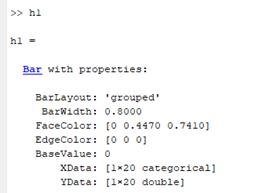

**Tree analogy**: the base object (known as the *structure*) is the trunk, the *fields/parameters* are the branches. Values in a field are associated with the "higher order" structure.

        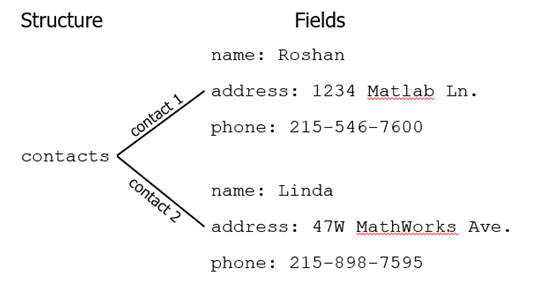

#### Creating a structure array

Fields in a structure array can be created or accessed using dot notation  (`.`).

% Create two fields for a structure array, a:
% a.b = 2;
% a.c.b = 'hello';
% a

The above structure array can be represented visually below. The fields `b` and `c` "belong" to structure array `a`. 

**Note**: `a.c` is a structure array itself!

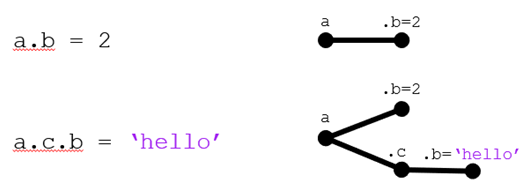

% Access field values
% a.b
% a.c
% a.c.b

**Any data type can be added to a structure array**. In the following, we add a numerical vector, a cell array, and a character array.

% a.c.c = [1,5,9];
% a.c.d = {'day',3};

Visually:

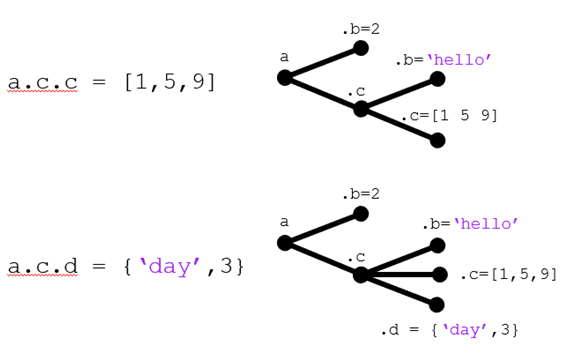

Furthermore, structure arrays can have a dimension greater than `1x1`:

% a(2).c.c = 'fun';

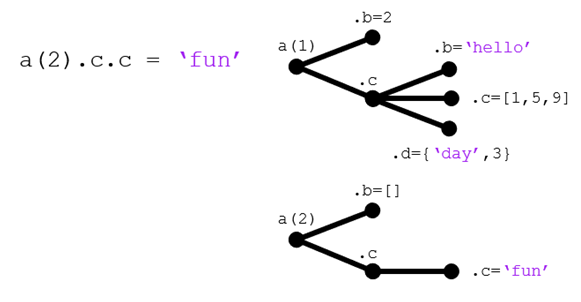

**Takeaway**: structure arrays are a useful way to organize data. A structure array and all fields within may be passed to a function or command by simply referring to the structure.

#### Relation to graphics objects

So far, we have used `get()` to visualize the parameters for a graphics object (e.g. plot) and `set()` to change the parameters. You can also use **dot notation to view or modify a parameter value**.

close all
x = 0:pi/24:2*pi;
y = sin(x);
h = plot(x,y,'k-');
axis square
get(h)

- Modification using `set()/get()`

% Change line color
set(h,'Color','r')

- Using dot notation on the structure/fields:

% Change line width
h.LineWidth = 3;
% Change line style
h.LineStyle = ':';

**Note**: even if you prefer dot notation, get() is still useful to identify potential parameters to change.

#### Example: visualizing "particle" movement

There are many cases in science and engineering where you may track the position of *some entity* over time. You could record the motion of fluorescent molecules, the run and tumble trajectories of bacteria, group dynamics of animal swarms, or human migration. In this problem: **given some recorded data, produce a visualization of the "particle" movement**.

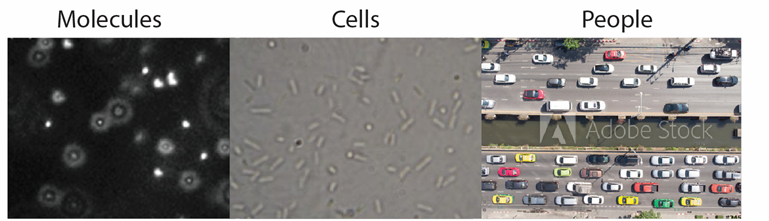

***Tips and notes:***

- `importdata()`, used above, can be used to incorporate mixed data (*e.g.* text and numbers).

- `pause` will halt MATLAB command execution for the specified time, in seconds.

- `rectangle` can be used to produce a square, rectangle, oval, or circle on the current axes.

% Import data as a structure array
myData = importdata('L18_TrackingData.txt')
% Numerical data
myData.data 
% Text data
myData.textdata

**Step 1****: start simple**. Write pseudocode and figure out how to plot "circles" for a given position

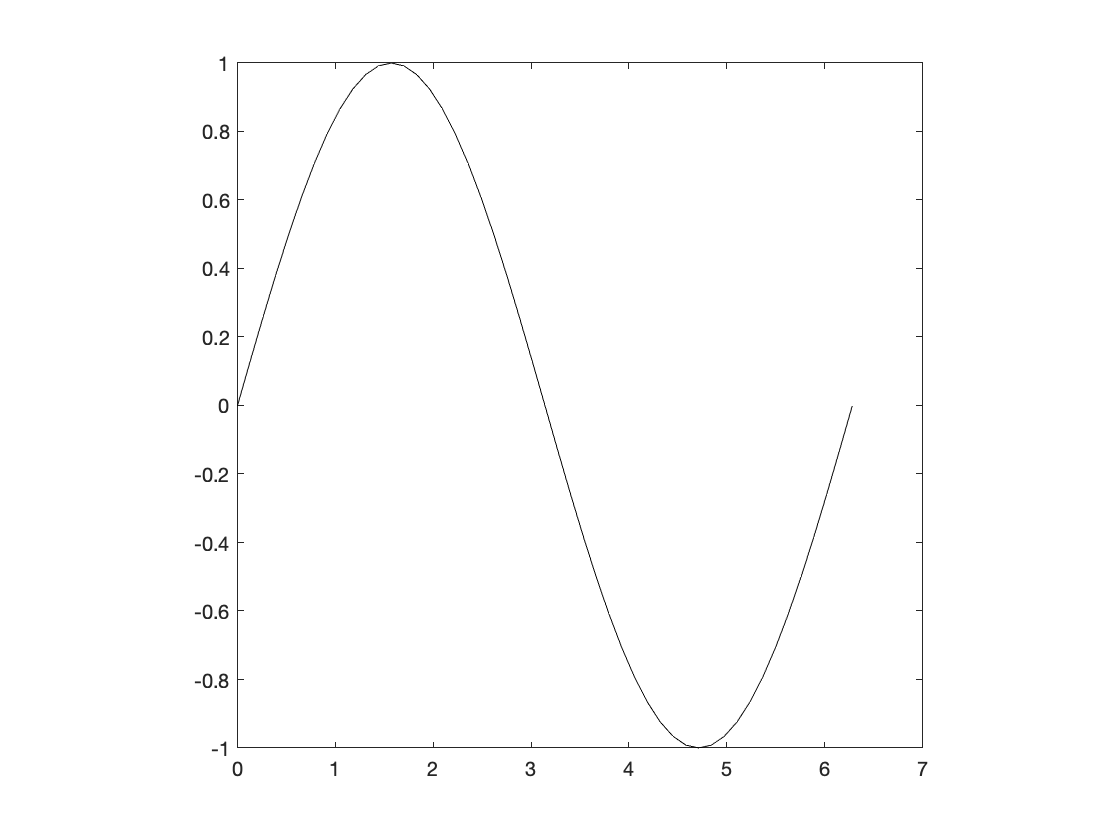

    AlignVertexCenters: off
            Annotation: [1×1 matlab.graphics.eventdata.Annotation]
          BeingDeleted: off
            BusyAction: 'queue'
         ButtonDownFcn: ''
              Children: [0×0 GraphicsPlaceholder]
              Clipping: on
                 Color: [0 0 0]
             ColorMode: 'manual'
           ContextMenu: [0×0 GraphicsPlaceholder]
             CreateFcn: ''
       DataTipTemplate: [1×1 matlab.graphics.datatip.DataTipTemplate]
             DeleteFcn: ''
           DisplayName: ''
      HandleVisibility: 'on'
               HitTest: on
         Interruptible: on
              LineJoin: 'round'
             LineStyle: '-'
         LineStyleMode: 'manual'
             LineWidth: 0.5000
                Marker: 'none'
       MarkerEdgeColor: 'auto'
       MarkerFaceColor: 'none'
         MarkerIndices: [1×49 uint64]
            MarkerMode: 'manual'
            MarkerSize: 6
                Parent: [1×1 Axes]
         PickableParts: 'visible'
         

close all % Close previous plots

% Create visualization: note 
h1 = rectangle('Position',[0,0,1,1],'Curvature',[1,1]);
h2 = rectangle('Position',[3,3,1,1],'Curvature',[1,1]);

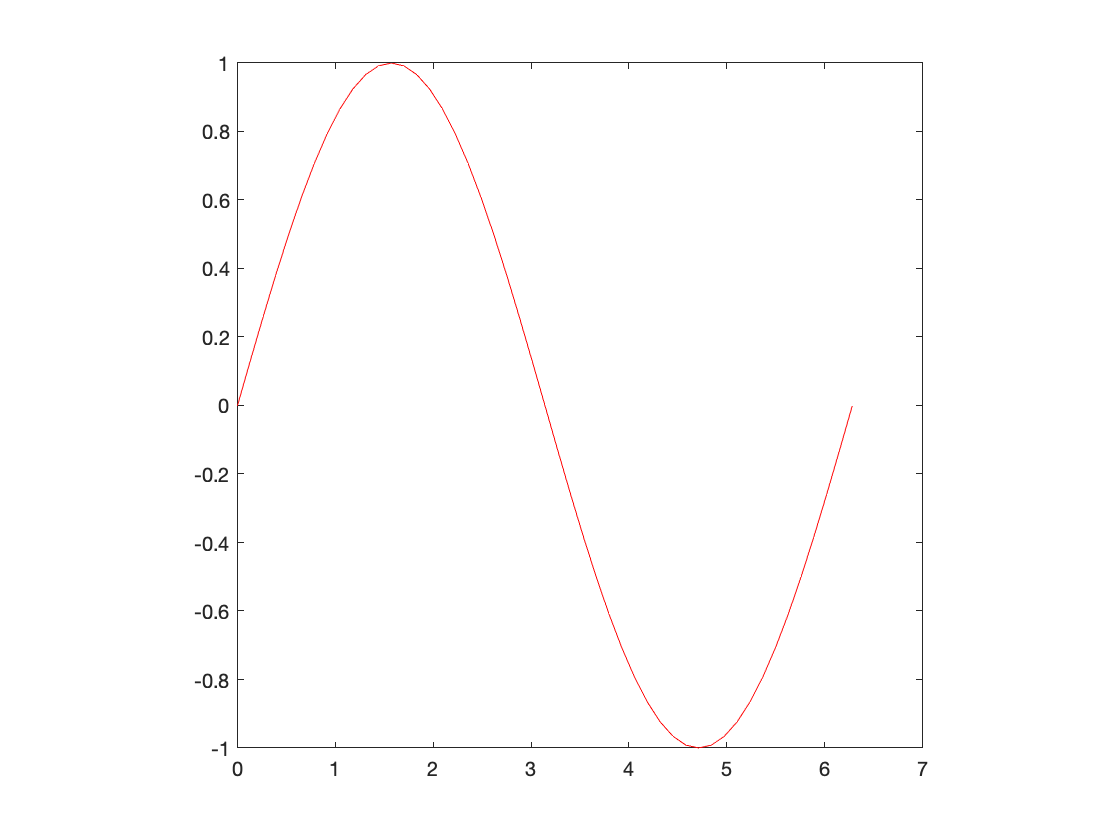

% Specify plotting parameters
axis square
xlim([0,10])
ylim([0,10])

**Step 2****: Convert data into a convenient format**. In this case, a structure array is good.

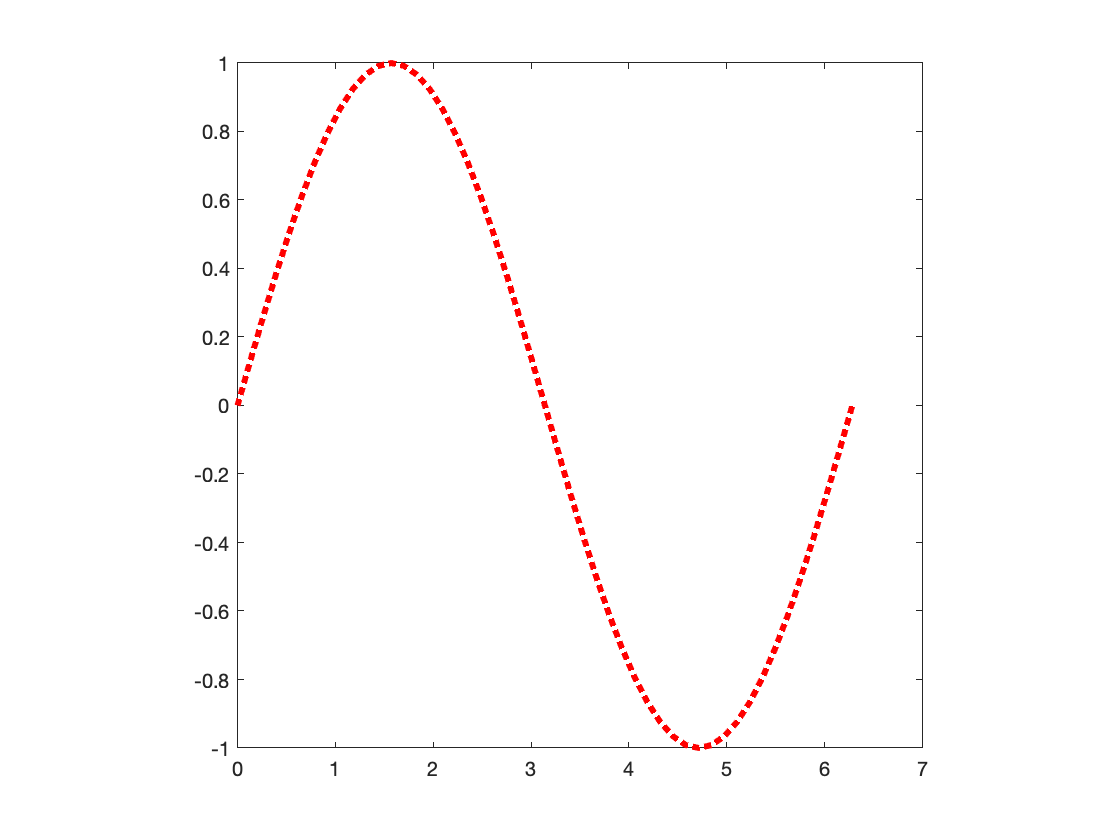

% Step 1: Create cell array of just particle identifiers
particle_ID = myData.textdata(2:end,1);

% Step 2: Create subarrays unique to each particle

A_data = myData.data(strcmp(particle_ID,'A'),:);
B_data = myData.data(strcmp(particle_ID,'B'),:);

% Step 3: Populate structure array with data for both particles
particle(1).ID = 'A';
particle(1).pos = A_data(:,1:2);
particle(1).dia = A_data(:,3);

particle(2).ID = 'B';

myData = struct with fields:
        data: [20×3 double]
    textdata: {21×4 cell}


particle(2).pos = B_data(:,1:2);
particle(2).dia = B_data(:,3);

ans =     3.0000    3.0000    1.0000
    3.0000    4.0000    1.5000
    4.0000    4.0000    2.0000
    4.0000    5.0000    2.5000
    5.0000    5.0000    3.0000
    6.0000    5.0000    2.5000
    7.0000    5.0000    2.0000
    8.0000    6.0000    1.5000
    8.0000    7.0000    1.0000
    7.0000    7.0000    0.5000



particle

ans = 21×4 cell array
    {'Marker'}    {'X'     }    {'Y'     }    {'Radius'}
    {'A'     }    {0×0 char}    {0×0 char}    {0×0 char}
    {'A'     }    {0×0 char}    {0×0 char}    {0×0 char}
    {'A'     }    {0×0 char}    {0×0 char}    {0×0 char}
    {'A'     }    {0×0 char}    {0×0 char}    {0×0 char}
    {'A'     }    {0×0 char}    {0×0 char}    {0×0 char}
    {'A'     }    {0×0 char}    {0×0 char}    {0×0 char}
    {'A'     }    {0×0 char}    {0×0 char}    {0×0 char}
    {'A'     }    {0×0 char}    {0×0 char}    {0×0 char}
    {'A'     }    {0×0 char}    {0×0 char}    {0×0 char}
    {'A'     }    {0×0 char}    {0×0 char}    {0×0 char}
    {'B'     }    {0×0 char}    {0×0 char}    {0×0 char}
    {'B'     }    {0×0 char}    {0×0 char}    {0×0 char}
    {'B'     }    {0×0 char}    {0×0 char}    {0×0 char}
    {'B'     }    {0×0 char}    {0×0 char}    {0×0 char}
    {'B'     }    {0×0 char}    {0×0 char}    {0×0 char}
    {'B'     }    {0×0 char}    {0×0 char}    {0×0 char}
    {'B' 

**Step 3****: Refine plotting code for one time point**

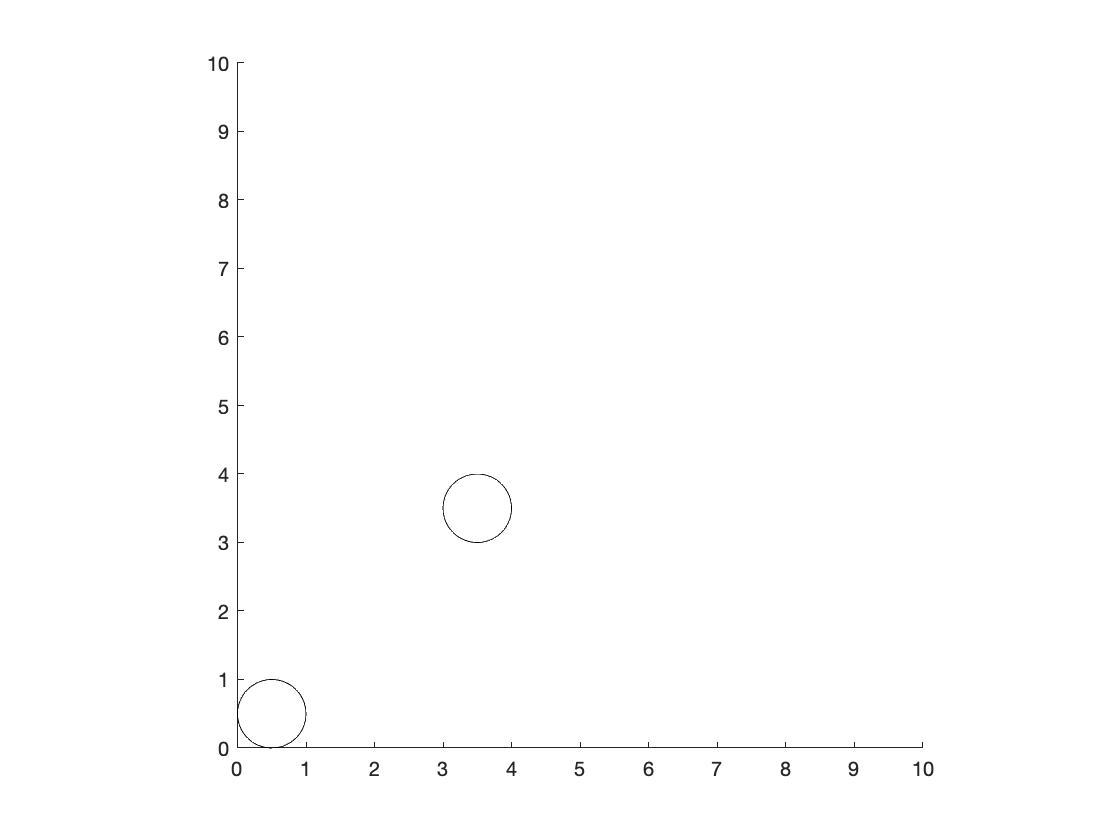

close all % Close previous plots 

% Goal: loop through all time points, i.e. all rows int he positional
% arrays

% Create axes and specify graphical parameters
g = axes;
axis square
xlim([0,10])
ylim([0,10])


% Create visualization: note the values of each position 
h(1) = rectangle('Position',[particle(1).pos(1,:),particle(1).dia(1)*[1,1]],'Curvature',[1,1]);
h(2) = rectangle('Position',[particle(2).pos(1,:),particle(2).dia(1)*[1,1]],'Curvature',[1,1]);


**Step 4****: Refine plotting code for all time point**

close all % Close previous plots

% Goal: loop through all time points, i.e. all rows in the positional
% arrays.

% Time points
timePts = size(particle(1).pos,1);

% Create axes and specify graphical paramters
axis square
xlim([0,10])
ylim([0,10])


particle = 1×2 struct array with fields:
    ID
    pos
    dia


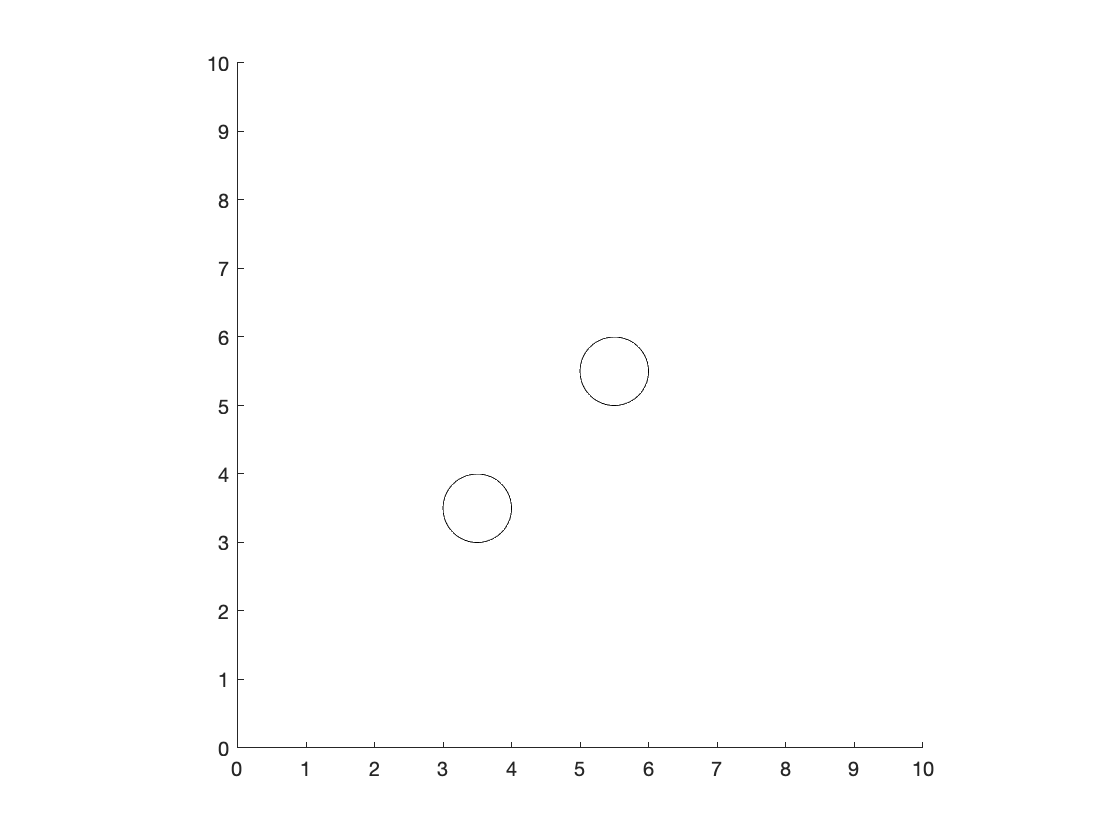

%Create Initial position of particles
h(1) = rectangle('Position',[particle(1).pos(1,:),particle(1).dia(1)*[1,1]],'Curvature',[1,1]);
h(2) = rectangle('Position',[particle(2).pos(1,:),particle(2).dia(1)*[1,1]],'Curvature',[1,1]);
% Specify colors
h(1).FaceColor = 'r';
h(2).FaceColor = 'g';

% Loop through all time points
for k = 2:timePts
    % Pause for 1 second
    pause(1)
    
    % Update position and radius for each particle
    for m = 1:2
        h(m).Position = [particle(m).pos(k,:),particle(m).dia(k)*[1,1]]; 
    end

end

disp('Done')

### Numeric data, audio, images, and video

***Remember***: to open a file by specifying only its name, the file must be located in the current directory

#### Importing data and reading files

**Numerical data**

- `csvread` - read numerical only csv files

- `importdata` - read numerical/text data files

% Read CSV file: Additional inputs specify "offset" to row/column to start
% reading from
data1 = csvread('L18_TrackingData.txt',1,1);

**Audio files**

- `audioread` - read audio files to a double array and **output sampling frequency**

**Image files**

- `imread` - read an image to an integer array

**Video files**

- `VideoReader` - creates a VideoReader object used to read a given video file

- `readFrame` - reads a frame of the VideoReader object

#### Exporting data and writing files

**Numerical data**

- `csvwrite` - write numerical only csv files

- `writecell` - write a cell to a csv file

**Audio files**

- `audiowrite` - write an array to an audio file based on the sampling frequency

**Image files**

- `imwrite` - write an integer array to an image file

**Video files**

- `VideoWriter` - creates a VideoWriter object used to write a given video file

- `writeVideo` - writes a frame of the VideoWriter object

#### Audio processing

An audio file may be read using the `audioread()` function.

% Read audio file
[y_signal,Fs] = audioread('clip0.mp4');

% Sampling frequency (Hz)
Fs

***Sampling frequency***: this refers to the number of points in a continuous time signal that are discretized.

- Computation occurs at discrete physical locations

- Memory is stored at discrete physical locations

- To process signals, we have to "approximate" these as a series of discrete points.

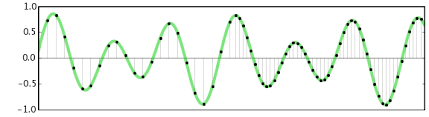

*Source: Audacity*

**Note**: most computers have an audio sampling frequency of 44.1 kHz, as above.

*There is a tradeoff**: A ****small**** sampling interval results in a ****better quality**** sound file but ****increases the size**** of the audio file*

**Note**: the size of the imported audio data often contains two "channels," or columns. This corresponds to **stereo** audio: the first column is output to the "left" speaker and the second column is output to the "right" speaker.

% Size of data
size(y_signal)

- `sound() `- may be used to listen to an audio signal

% Listen to sound
sound(y_signal,Fs)

**Note**: the output sound differs in stero, mono, or with output only coming from certain speakers.

% Listen to the first channel in mono
sound(y_signal(:,1),Fs)

% Listen to only the first channel in stereo: you should only hear it in
% one side of your headphones/speakers
sound([y_signal(:,1),zeros(size(y_signal(:,1)))],Fs)

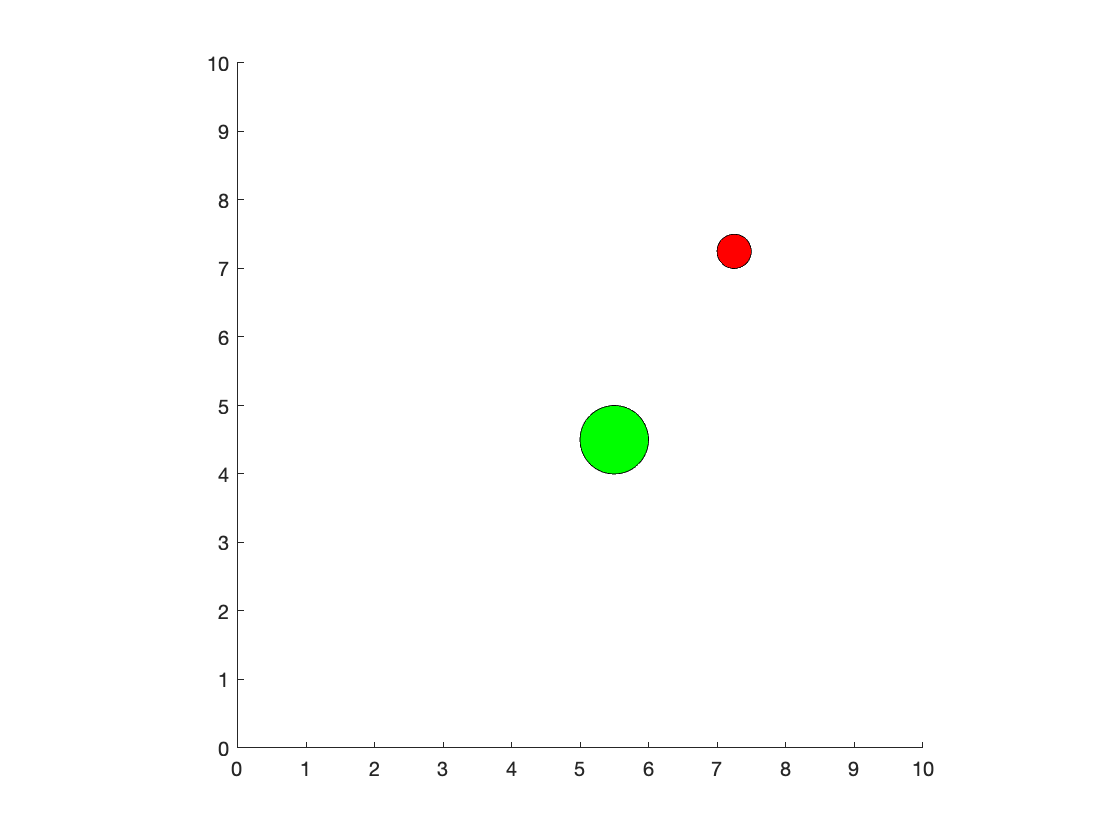

% Listen to only the first channel in stereo: you should only hear it in
% the other side of your headphones/speakers
sound([zeros(size(y_signal(:,1))),y_signal(:,1)],Fs)

% Plot audio signal
t = 1/Fs*(1:size(y_signal,1));

Done


Fs = 44100

ans =       439232           2


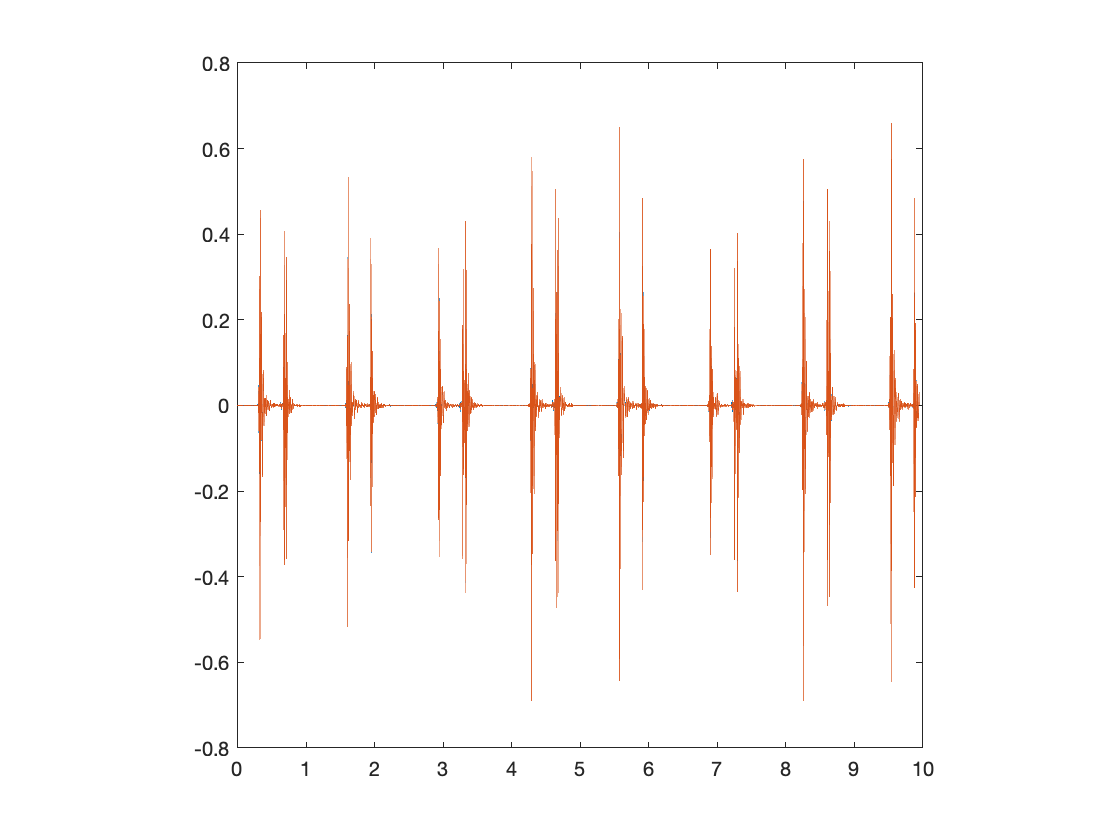

plot(t,y_signal)
axis square